% Position and angle matrices
position_mid = [0.9,1.8,2.7,3.6];
position_side = 0.9*(0:8)+5.6;
position_out = 0.9*(0:4)+15;
positions = [-flip(position_out), -flip(position_side), -flip(position_mid), 0, position_mid, position_side, position_out]

positions =   -18.6000  -17.7000  -16.8000  -15.9000  -15.0000  -12.8000  -11.9000  -11.0000  -10.1000   -9.2000   -8.3000   -7.4000   -6.5000   -5.6000   -3.6000   -2.7000   -1.8000   -0.9000         0    0.9000    1.8000    2.7000    3.6000    5.6000    6.5000    7.4000    8.3000    9.2000   10.1000   11.0000   11.9000   12.8000   15.0000   15.9000   16.8000   17.7000   18.6000


theta1 = atan(positions/19.5);
theta1 = theta1';

thetaAS = atan((positions)/19.5);
thetaAS = thetaAS';

thetaVEML = atan((positions)/19.5);
thetaVEML = thetaVEML';


h = 19.5;
r = sqrt((19.5^2 + positions.^2))

r =    26.9483   26.3351   25.7389   25.1607   24.6018   23.3257   22.8443   22.3886   21.9604   21.5613   21.1929   20.8569   20.5548   20.2882   19.8295   19.6860   19.5829   19.5208   19.5000   19.5208   19.5829   19.6860   19.8295   20.2882   20.5548   20.8569   21.1929   21.5613   21.9604   22.3886   22.8443   23.3257   24.6018   25.1607   25.7389   26.3351   26.9483


t = 1

t = 1

DIST_AS = reshape(cell2mat(DISTas(:,t)),[],15);
DIST_AS_CLEAR = DIST_AS(:,9);
DIST_AS_Normalised = DIST_AS(:,1:9)./DIST_AS(6,1:9);
DIST_AS_Normalised_CLEAR = DIST_AS_Normalised(:,9);

f_AS = fit(d',DIST_AS_Normalised_CLEAR,'exp2',opts);

% -----------------------------------------------------
DIST_VEML = reshape(cell2mat(DISTveml(:,t)),[],15);
DIST_VEML_Normalised = DIST_VEML(:,11:14)./DIST_VEML(6,11:14);
DIST_VEML_Normalised_CLEAR = DIST_VEML_Normalised(:,4);
f_VEML = fit(d',DIST_VEML_Normalised_CLEAR,'exp2');

f_AS(r)

ans =     0.0325
    0.0342
    0.0359
    0.0378
    0.0396
    0.0442
    0.0461
    0.0480
    0.0498
    0.0516


f_AS(19.5)./f_AS(r)

ans =     1.9188
    1.8219
    1.7322
    1.6491
    1.5723
    1.4089
    1.3513
    1.2985
    1.2505
    1.2071


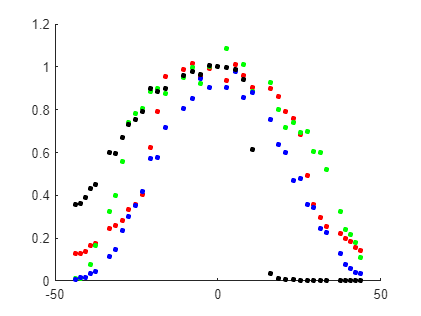

t = 3;
% Get data and scale the different integration times
WHITE_100_Angles_Further_Scaled = scale(WHITE_100_Angles_Further);
W_100_Further_M = transpose(reshape(cell2mat(WHITE_100_Angles_Further_Scaled(:,t)),9,15));
WHITE_100_Angles_Further_L_Scaled = scale2(WHITE_100_Angles_Further_L);
W_100_Further_L = transpose(reshape(cell2mat(WHITE_100_Angles_Further_L_Scaled(:,t)),[],15));
WHITE_100_Angles_Further_R_Scaled = scale2(WHITE_100_Angles_Further_R);
W_100_Further_R = transpose(reshape(cell2mat(WHITE_100_Angles_Further_R_Scaled(:,t)),[],15));

W_100_Further = [W_100_Further_R, W_100_Further_M, W_100_Further_L];

W_100_Further_normaliseW_AS = W_100_Further(1:9,:)./W_100_Further(1:9,19);
W_100_Further_normaliseW_VEML = W_100_Further(11:14,:)./W_100_Further(11:14,19);

% AS7341 Colour scatter
scatter(rad2deg(theta1), W_100_Further_normaliseW_AS([7, 4, 2, 9],:), 15, VEML_Colours, 'filled')

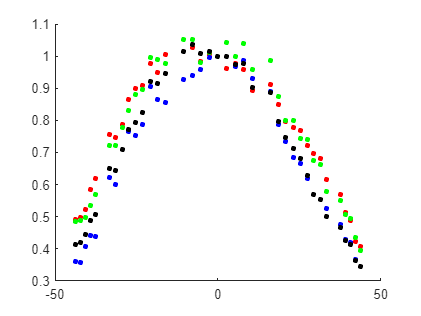


% hold on
% % scatter(theta, W_100_normaliseW_AS(:,[7, 4, 2, 9]),5,"cyan")
% hold off
% scatter(theta1, W_100_Further_normaliseW_AS(7,:), [], 'red')
% scatter(theta1, W_100_Further_normaliseW_AS(4,:), [], 'green')
% scatter(theta1, W_100_Further_normaliseW_AS(2,:), [], 'blue')

% VEML6040 Colour scatter
scatter(rad2deg(theta1), W_100_Further_normaliseW_VEML(1:4,:), 15, VEML_Colours, 'filled')

% hold on
% scatter(theta, W_100_normaliseW_VEML(:,1:4),5,"cyan")
% hold off
% scatter(theta1, W_100_Further_normaliseW_VEML(1,:), [], 'red')
% scatter(theta1, W_100_Further_normaliseW_VEML(2,:), [], 'green')
% scatter(theta1, W_100_Further_normaliseW_VEML(3,:), [], 'blue')

scaling_factor_LED = cos(theta1)'

scaling_factor_LED =     0.7236    0.7405    0.7576    0.7750    0.7926    0.8360    0.8536    0.8710    0.8880    0.9044    0.9201    0.9349    0.9487    0.9612    0.9834    0.9905    0.9958    0.9989    1.0000    0.9989    0.9958    0.9905    0.9834    0.9612    0.9487    0.9349    0.9201    0.9044    0.8880    0.8710    0.8536    0.8360    0.7926    0.7750    0.7576    0.7405    0.7236


scaling_factor_distance_AS = f_AS(19.5)./f_AS(r)

scaling_factor_distance_AS =     1.9188
    1.8219
    1.7322
    1.6491
    1.5723
    1.4089
    1.3513
    1.2985
    1.2505
    1.2071


scaling_factor_distance_VEML = f_VEML(19.5)./f_VEML(r)

scaling_factor_distance_VEML =     1.8583
    1.7674
    1.6832
    1.6052
    1.5332
    1.3802
    1.3262
    1.2770
    1.2322
    1.1917


scaling_factor_AS = scaling_factor_distance_AS.*scaling_factor_LED'

scaling_factor_AS =     1.3884
    1.3490
    1.3123
    1.2781
    1.2463
    1.1779
    1.1534
    1.1310
    1.1104
    1.0917


scaling_factor_VEML = scaling_factor_distance_VEML.*scaling_factor_LED'

scaling_factor_VEML =     1.3446
    1.3087
    1.2752
    1.2441
    1.2153
    1.1538
    1.1321
    1.1122
    1.0941
    1.0778


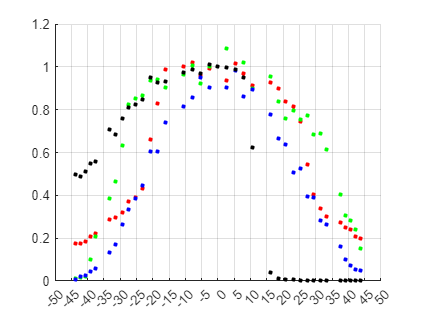


AS = W_100_Further_normaliseW_AS([7, 4, 2, 9],:).*scaling_factor_AS';

VEML = W_100_Further_normaliseW_VEML(1:4,:).*scaling_factor_VEML';

 % t = -50:0.01:50;
 % x = cos(deg2rad(t));
 % plot(t,x,'k');

% scatter(rad2deg(theta1), AS, 10, VEML_Colours, 'filled')
% xticks(-50:5:50)
% grid on
scatter(rad2deg(thetaAS), AS, 10, VEML_Colours, 'filled')
xticks(-50:5:50)
grid on

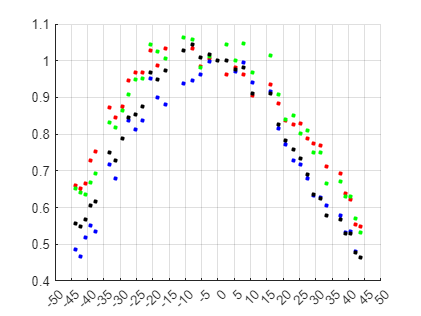


scatter(rad2deg(thetaVEML), VEML, 10, VEML_Colours, 'filled')
xticks(-50:5:50)
grid on

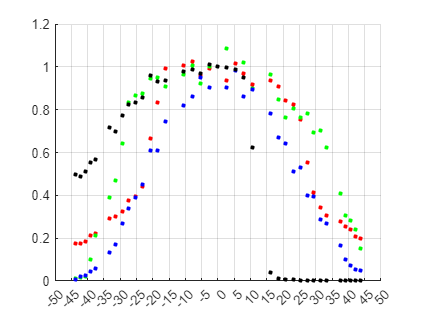


AS = W_100_Further_normaliseW_AS([7, 4, 2, 9],:)./scaling_factor_LED;

VEML = W_100_Further_normaliseW_VEML(1:4,:)./scaling_factor_LED;
scatter(rad2deg(thetaAS), AS, 10, VEML_Colours, 'filled')
xticks(-50:5:50)
grid on

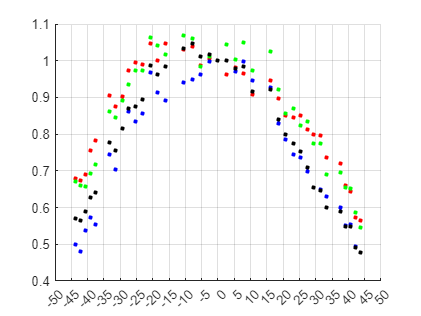


scatter(rad2deg(thetaVEML), VEML, 10, VEML_Colours, 'filled')
xticks(-50:5:50)
grid on


AS_R = AS(1,:);
AS_G = AS(2,:);
AS_B = AS(3,:);
AS_W = AS(4,:);

VEML_R = VEML(1,:);
VEML_G = VEML(2,:);
VEML_B = VEML(3,:);
VEML_W = VEML(4,:);

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(9,4);
    for j = 1:9
        for i = 1:4
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

function COLOUR_Scaled = scale2(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(14,4);
    for j = 1:14
        for i = 1:4
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

% function ANGLE_Scale